# Taller 4

### 05/09/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre el primer Quiz*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Notas frente al uso de los métodos:*

#### *        Métodos de una variable*

`    [c, err, n] = bisect(Function, Num1, Num2, Tol), `Método de bisección.

            - Function funcion definida @

            - Num1 y Num2 son los extremos del intervalo

            - Tol Es la tolerancia definida a la iteración

            - c es la aproximación obtenida por el método

            - err Error asociado a la iteración

            - n Pasos realizados para alcanzar la tolerancia

`    [p, k, err, P] = fixpt(g, p0, tol, max1), `Método de punto fijo.

            - g funcion creada con @

            - p0 es el supuesto inicial para el punto fijo

            - tol es la tolerancia

            - max1 es el numero maximo de iteraciones

            - p es la aproximacion del punto fijo

            - k es el numero de iteraciones realizadas

            - err es el error en la aproximacion

            - P' contiene la secuencia {pn}

`    [p, err, k, yc] = newton(f, df, p0, delta, epsilon, max1), `Método de Newton.

            - f funcion creada con @

            - df funcion derivada creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

`    [p, err, k, yc] = newton(f, df, d2f, p0, delta, epsilon, max1), `Método de Newton modificado.

            - f funcion creada con @

            - df primera derivada, funcion creada con @

            - d2f segunda derivada, funcion creada con @

            - p0 es la aproximacion inicial a cero de  f

            - delta es la tolerancia para  p0

            - epsilon es la tolerancia para los valores de la funcion  y

            - max1 es el numero maximo de iteraciones

            - p0 es la aproximacion de Newton-Raphson hacia cero

            - err es el error estimado para  p0

            - k es el numero de iteraciones

            - y es el valor de la funcion  f(p0)

*Frente a la definición del método de Newton acelerado, recordemos que este puede ser invocado usando el método de Newton y agrendando la multiplicidad de la raiz a hallar en la definición de la función o en la definición de la derivada de la función, tal como se indica:*

$x_{k+1} =x_k -M\frac{\;f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$ : Definimos entonces $f\left(x_k \right):=M\;f\left(x\right)\;|\;f^{\prime } \left(x_k \right):=\frac{f^{\prime } \left(x\right)}{M}$.

#### *        Métodos de sistemas de ecuaciones*

`    X = jacobi(A, B, P, delta, max1), `Método de Jacobi.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; los supuestos iniciales

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de jacobi a

                la solucion de  AX = B

`    X = gseid(A, B, P, delta, max1), `Método de Gauss - Seidel.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de gauss-seidel a

                la solucion de  AX = B

`    Y = sor(A, B, P, w, delta, max1), `Método de SOR

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - w parametro de sobrerelajacion (0<w<2)

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

             - Y es una matriz  N x 1: la aproximacion de SOR a

                la solucion de  AX = B

`    P = newdim (F, JF, P, delta, epsilon, max1), `Método de Newton

            - F funcion del sistema creada con @

            - JF matriz jacobiana, funcion creada con @

            - P es la aproximacion inicial a la solucion

            - delta es la tolerancia para  P

            - epsilon es la tolerancia para  F(P)

            - max1 es el numero maximo de iteraciones

            - P es la aproximacion a la solucion

            - iter es el numero de iteraciones realizadas

            - err es el error estimado para  P

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

### Sistemas lineales y no lineales

*Desarrollaremos el cuarto taller, para esta primera sección resolveremos *$\left.\left.\left.\left.\left.\left.1\right),\;2\right)\;3\right),6\right),7\right)\;y\;8\right)$.

**1. **Considere la matriz $A=\left\lbrack \begin{array}{cc}
2 & 3\\
1 & 4
\end{array}\right\rbrack$ . Demuestre que $A$ **no es estrictamente dominante diagonalmente** (por filas) pero que los métodos iterativos de Jacobi y Gauss-Seidel para resolver cualquier sistema con matriz $A$, convergen.

clear

A = [2 3; 1 4];
edd(A);

La matriz no es e.d.d.

[~] = Jac_GS(A)

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 0.6124

ratioTGS = 0.3750

ratioTw = 0.3750

**2. **En cada caso, utilice el método de SOR con $\omega =1\ldotp 1:\;\ldotp 1:1\ldotp 6$ *(notación MATLAB) *para aproximar las soluciones de los sistemas lineales $A\;x=b$. En todos los casos use máximo número de iteraciones igual a `maxiter=3000`, tolerancia `delta=1e-5` y el vector nulo como primera aproximación. *Determine las normas de los vectores residual y error. Use la norma 2.*

**    a)** $A=\left\lbrack \begin{array}{ccccc}
4 & 1 & 1 & 0 & 1\\
-1 & -3 & 1 & 1 & 0\\
2 & 1 & 5 & -1 & -1\\
-1 & -1 & -1 & 4 & 0\\
0 & 2 & -1 & 1 & 1
\end{array}\right\rbrack$    $b=4\;\left\lbrack \begin{array}{c}
1\\
1\\
1\\
1\\
1
\end{array}\right\rbrack$

**    b)** `A = gallery('dorr', 10); b = A*ones(10, 1); p = zeros(10,1)`

**    c)** La matriz $A={\left\lbrack a_{i\;j} \right\rbrack }_{20\textrm{x20}}$ dada por:


$$a_{i\;j} =\left\lbrace \begin{array}{ll}
4:\;i\;=j & -1:i=j+1\\
-1:\;i=j-1 & 0:\textrm{otro}\;\textrm{caso}
\end{array}\right.$$


`    b = A*ones(10, 1); p = zeros(10,1)`

clear

A = gallery('dorr', 10); b = A*ones(10, 1); p = zeros(size(b));
X = ones(10, 1);

for w = 1.1:.1:1.6
    w
    X0 = sor(A, b, p, w, 1e-5, 3000);
    residual = norm(b - A * X0)
    error = norm(X - X0)
end

w = 1.1000

residual = 8.3063e-05

error = 0.0096

w = 1.2000

residual = 7.4646e-05

error = 0.0079

w = 1.3000

residual = 6.8028e-05

error = 0.0063

w = 1.4000

residual = 6.3163e-05

error = 0.0050

w = 1.5000

residual = 5.9652e-05

error = 0.0039

w = 1.6000

residual = 5.6990e-05

error = 0.0029

clear

A = gallery('tridiag', 10, -1, 4, -1);
X = ones(10, 1);
B = A * X;
P = zeros(size(B));

for w = 1.1:.1:1.6
    w
    X0 = sor(A, B, P, w, 1e-5, 3000);
    residual = norm(B - A * X0)
    error = norm(X - X0)
end

w = 1.1000

residual = 3.4230e-05

error = 6.8328e-06

w = 1.2000

residual = 1.6206e-05

error = 3.3968e-06

w = 1.3000

residual = 3.9081e-05

error = 8.8134e-06

w = 1.4000

residual = 8.5858e-06

error = 3.2178e-06

w = 1.5000

residual = 1.3439e-05

error = 4.2377e-06

w = 1.6000

residual = 2.6280e-05

error = 7.8520e-06

**3. **Pruebe que las iteraciones de Gauss Seidel y SOR son convergentes pero la de Jacobi no lo es para todo sistema de ecuaciones con matriz `A = toeplitz([4, 3, 1])`

clear

A = toeplitz([4, 3, 1]);
[~] = Jac_GS(A)

No se declara w, por lo tanto la matriz SOR es Gauss Seidel
Radio Espectral


ratioTJ = 1.1930

ratioTGS = 0.8886

ratioTw = 0.8886

eigs(A)

ans =     8.7720
    3.0000
    0.2280


for w = .1:.05:1.9
    [~] = Jac_GS(A, w)
end

ratioTw = 0.9940

ratioTw = 0.9908

ratioTw = 0.9874

ratioTw = 0.9838

ratioTw = 0.9801

ratioTw = 0.9761

ratioTw = 0.9718

ratioTw = 0.9674

ratioTw = 0.9626

ratioTw = 0.9575

ratioTw = 0.9520

ratioTw = 0.9462

ratioTw = 0.9399

ratioTw = 0.9331

ratioTw = 0.9257

ratioTw = 0.9177

ratioTw = 0.9090

ratioTw = 0.8993

ratioTw = 0.8886

ratioTw = 0.8767

ratioTw = 0.8632

ratioTw = 0.8479

ratioTw = 0.8301

ratioTw = 0.8091

ratioTw = 0.7834

ratioTw = 0.7507

ratioTw = 0.7053

ratioTw = 0.6238

ratioTw = 0.5637

ratioTw = 0.6082

ratioTw = 0.6526

ratioTw = 0.6969

ratioTw = 0.7410

ratioTw = 0.7849

ratioTw = 0.8285

ratioTw = 0.8718

ratioTw = 0.9149

**6) **Considere el sistema $\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=0$, donde:


$$\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{c}
4\;x_1^{\;3} -27\;x_1 \;x_{2\;}^{\;2} +25\\
4\;x_1^{\;2} -3x_2^{\;3} -1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Utilice el método de Newton para aproximar el único punto de intersección ente las curvas

clear
syms f(x, y)
syms x y real

f(x, y) = [4*x^3 - 27* x*y^2 + 25, 4*x^2- 3*y^3 - 1]'

$$f(x, y) = \left(\begin{array}{c} 4\,x^{3}-27\,x\,y^{2}+25\\ 4\,x^{2}-3\,y^{3}-1 \end{array}\right)$$

help newdim

  Entrada  - F funcion del sistema creada con @
             JF matriz jacobiana, funcion creada con @
           - P es la aproximacion inicial a la soluion
           - delta es la tolerancia para  P
           - epsilon es la tolerancia para  F(P)
           - max1 es el numero maximo de iteraciones
  Salida   - P es la aproximacion a la solucion
           - iter es el numero de iteraciones realizadas
           - err es el error estimado para  P



J(x, y) = jacobian(f, [x, y])

$$J(x, y) = \left(\begin{array}{cc} 12\,x^{2}-27\,y^{2} & -54\,x\,y\\ 8\,x & -9\,y^{2} \end{array}\right)$$

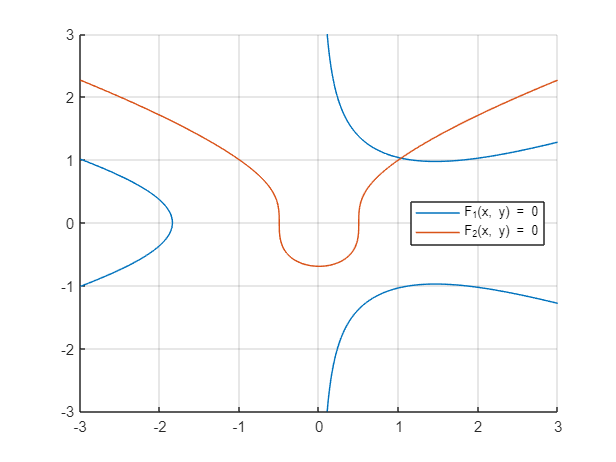

f = matlabFunction(f); J = matlabFunction(J);
f = @(X) f(X(1), X(2)); J = @(X) J(X(1), X(2));

f1(x, y) = 4.*x.^3 - 27* x.*y.^2 + 25; f2(x, y) = 4*x^2- 3*y^3 - 1;

clf("reset")
hold on
fimplicit(f1 == 0, [-3, 3], 'DisplayName', 'F_1(x, y) = 0')
fimplicit(f2 == 0, [-3, 3], 'DisplayName', 'F_2(x, y) = 0')
grid on
legend('Location', 'best')

X = newdim(f, J, [1 1]', 1e-15, 1e-15, 100)

X =     1.0311
    1.0274


**7) **Considere el sistema $\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=0$, donde:


$$\mathit{\mathbf{F}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{c}
x_1^{\;2} +x_1 \;x_2 \;x_3 +x_3^{\;3} \\
x_1^{\;3} \;x_2 +x_2 \;x_3^{\;2} \\
x_1 \;/x_2^{\;3} 
\end{array}\right\rbrack$$


Utilice el método de Newton para encontrar una solución de este sistema. Como primera aproximación use `ones(1,3)`. 

clear

syms f(x, y, z)
syms x y z real

f(x, y, z) = [x^2 + x * y * z + z^3, x^3*y + y*z^2, x / y^3]';
J(x, y, z) = jacobian(f, [x, y, z]);

f = matlabFunction(f); J = matlabFunction(J);
f = @(X) f(X(1), X(2), X(3)); J = @(X) J(X(1), X(2), X(3));

X = newdim(f, J, ones(1, 3)', 1e-3, 1e-3, 100)

X =     0.0000
    0.0066
   -0.0003


**8. **Utilice el método de Newton para aproximar la raiz del sistema


$$\begin{array}{l}
x^3 +3y^2 =21\\
x^2 +2y+2=0
\end{array}$$
            
$$\begin{array}{l}
1-x^2 -y^2 =0\\
1-e^x -y=0
\end{array}$$
 

Como primera aproximación considerar $x_0 =\;\left\lbrack \begin{array}{c}
1\\
1
\end{array}\right\rbrack$

clear
syms f(x, y)
syms x y real

f(x, y) = [x^3 + 3*y^2 - 21, x^2 + 2*y + 2]'

$$f(x, y) = \left(\begin{array}{c} x^{3}+3\,y^{2}-21\\ x^{2}+2\,y+2 \end{array}\right)$$

J(x, y) = jacobian(f, [x, y])

$$J(x, y) = \left(\begin{array}{cc} 3\,x^{2} & 6\,y\\ 2\,x & 2 \end{array}\right)$$

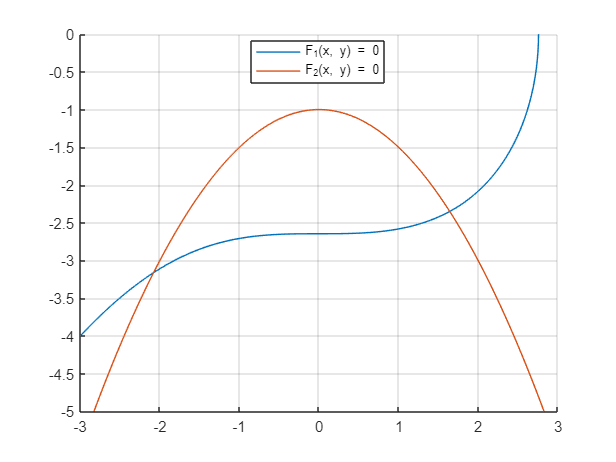

f = matlabFunction(f); J = matlabFunction(J);
f = @(X) f(X(1), X(2)); J = @(X) J(X(1), X(2));

f1(x, y) = x^3 + 3*y^2 - 21; f2(x, y) = x^2 + 2*y + 2;

clf("reset")
hold on
fimplicit(f1 == 0, [-3, 3, -5, 0], 'DisplayName', 'F_1(x, y) = 0')
fimplicit(f2 == 0, [-3, 3, -5, 0], 'DisplayName', 'F_2(x, y) = 0')
grid on
legend('Location', 'best')

X = newdim(f, J, ones(2, 1), 1e-15, 1e-15, 100)

X =     1.6430
   -2.3498


X = newdim(f, J, -2*ones(2, 1), 1e-15, 1e-15, 100)

X =    -2.0793
   -3.1617


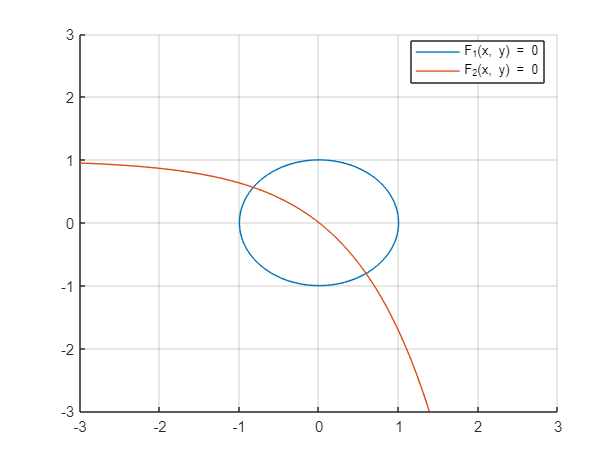

clear
syms f(x, y)
syms x y real

f(x, y) = [1 - x^2 - y^2, 1 - exp(x) - y]';
J(x, y) = jacobian(f, [x, y]);
f = matlabFunction(f); J = matlabFunction(J);
f = @(X) f(X(1), X(2)); J = @(X) J(X(1), X(2));

f1(x, y) = 1 - x^2 - y^2; f2(x, y) = 1 - exp(x) - y;

clf("reset")
hold on
fimplicit(f1 == 0, [-3, 3], 'DisplayName', 'F_1(x, y) = 0')
fimplicit(f2 == 0, [-3, 3], 'DisplayName', 'F_2(x, y) = 0')
grid on
legend('Location', 'best')

X = newdim(f, J, ones(2, 1), 1e-15, 1e-15, 100)

X =    -0.8268
    0.5625


X = newdim(f, J, [1, -1]', 1e-15, 1e-15, 100)

X =     0.5913
   -0.8064
